# PRACTICA: RAÍCES NUMÉRICAS DE FUNCIONES NO LINEALES

Gráficamente podemos estimar las raices de una función y localizarlas visualmente, sin embargo vamos a utlizar los métodos numéricos vistos.

A continuación, aplicamos los métodos implementados para hallar la raíz positiva de la función definida por:

clear var
syms x
f(x) = x*sin((1/2)*x^2)+exp(-x)

$$f(x) = {\mathrm{e}}^{-x}+x\,\sin\left(\frac{x^{2}}{2}\right)$$

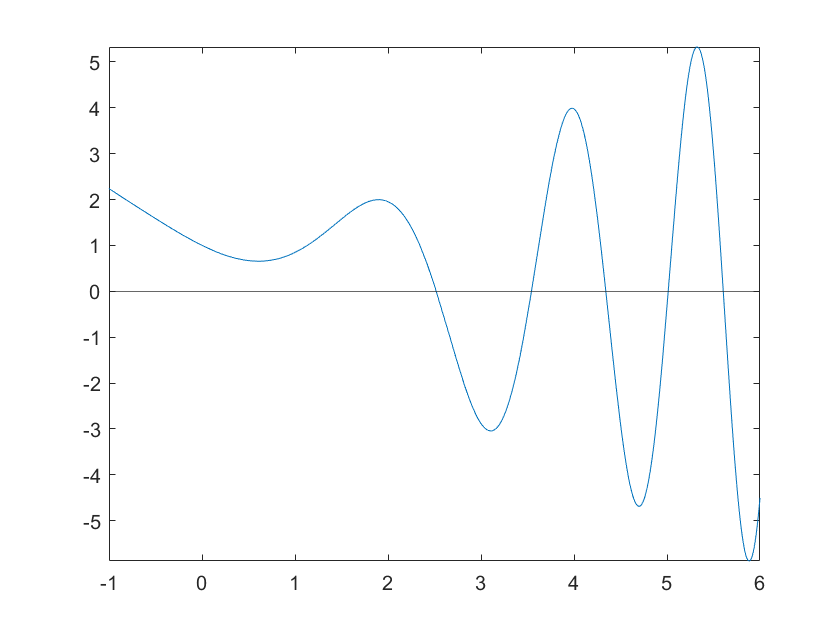

%fplot(f,[0 20])
fplot(f,[-1 6])
yline(0)

e=1*10^-5

e =      9.999999999999999e-06


### Método de bisección

format long
x0_x= vpa(biseccion(f,0,1,e));

Método de bisección
No existen raices en el intervalo [x1,x2].

x0_r= vpa(fzero(f,[0 1]))

$$x0\_r = 0.00000000000000088817841970012523233890533447266$$


x0_x1= vpa(biseccion(f,1,3,e));

Método de bisección

Raiz= 2.519341 en 18 iteraciones

%options = optimset('PlotFcns',{@optimplotx,@optimplotfval});
options = optimset('Display','iter');
x0_r1= vpa(fzero(f,[1 3],options))

 
 Func-count    x          f(x)             Procedure
    2               1      0.847305        initial
    3         1.45431       1.50045        interpolation
    4         2.22715       1.47596        bisection
    5         2.61358     -0.633413        bisection
    6         2.80679      -1.94805        bisection
    7         2.90339      -2.49655        bisection
    8          2.9517      -2.71424        bisection
    9         2.97585      -2.80518        bisection
   10         2.98792      -2.84572        bisection
   11         2.99396       -2.8647        bisection
   12         2.99698      -2.87386        bisection
   13         2.99849      -2.87836        bisection
   14         2.99925      -2.88059        bisection
   15         2.99962       -2.8817        bisection
   16         2.99981      -2.88225        bisection
   17         2.99991      -2.88253        bisection
   18         2.99995      -2.88267        bisection
   19         2.99998      -2.88273       

$$x0\_r1 = 2.9999999999999986271478015362832$$


x0_x2= vpa(biseccion(f,3,4,e));

Método de bisección

Raiz= 3.542610 en 17 iteraciones

x0_r2= vpa(fzero(f,[3 4]))

$$x0\_r2 = 3.9789151253497723680692976516974$$


x0_x3= vpa(biseccion(f,4,5,e));

Método de bisección

Raiz= 4.342293 en 17 iteraciones

x0_r3= vpa(fzero(f,[4 5]))

$$x0\_r3 = 4.0000000000000032843394632622098$$


x0_x4= vpa(biseccion(f,2.8,3.2,e));

Método de bisección
No existen raices en el intervalo [x1,x2].

x0_r4= vpa(fzero(f,[2.8 3.2]))

$$x0\_r4 = 3.1049543396283527663115364703117$$

### Método de Newton-Raphson

format long
x0_x5= vpa(newtonRaphson(f,3.3,e));

Método de Newton-Raphson

Raiz= 3.542603 hallado en 4 iteraciones.

x0_r5= vpa(fzero(f,3.3))

$$x0\_r5 = 3.2066619048833775451612382312305$$


%No converge
%x0_x6= vpa(newtonRaphson(f,4,e));
x0_r6= vpa(fzero(f,4))

$$x0\_r6 = 3.9789151253497756499655224615708$$


x0_x7= vpa(newtonRaphson(f,5,e));

Método de Newton-Raphson

Raiz= 5.012992 hallado en 3 iteraciones.

x0_r7= vpa(fzero(f,5))

$$x0\_r7 = 4.8585786437626943268242030171677$$


x0_x8= vpa(newtonRaphson(f,6,e));

Método de Newton-Raphson

Raiz= 6.139903 hallado en 4 iteraciones.

x0_r8= vpa(fzero(f,6))

$$x0\_r8 = 5.8834889014719413680154502799269$$